load pnts.mat

myStr=mat2str(pntsTest1)

myStr = '[-0.078525997698307 -0.112035997211933 -0.470306992530823 0.421945989131927 -0.0415760017931461;0.0820880010724068 -0.244963005185127 -0.249103993177414 -0.206649005413055 -0.506470024585724;1.71200001239777 1.56099998950958 1.51900005340576 1.6360000371933 1.68499994277954]'

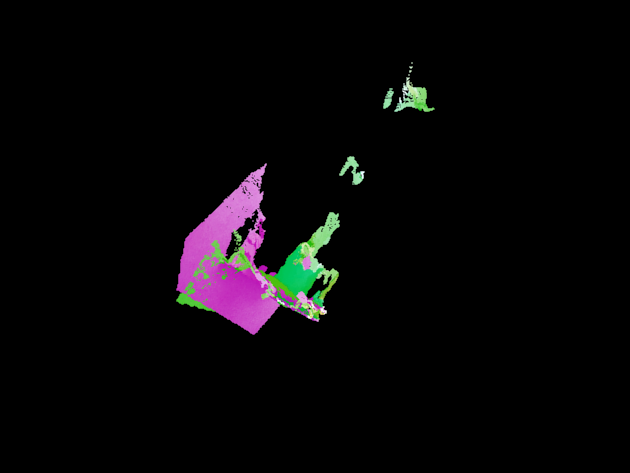

[R, T, err] = absoluteOrientationQuaternion(pntsTest1,pntsTest2);
tform = rigidtform3d(R,T);

pcNew=pctransform(pc1,tform);
pcshowpair(pcNew,pc2);

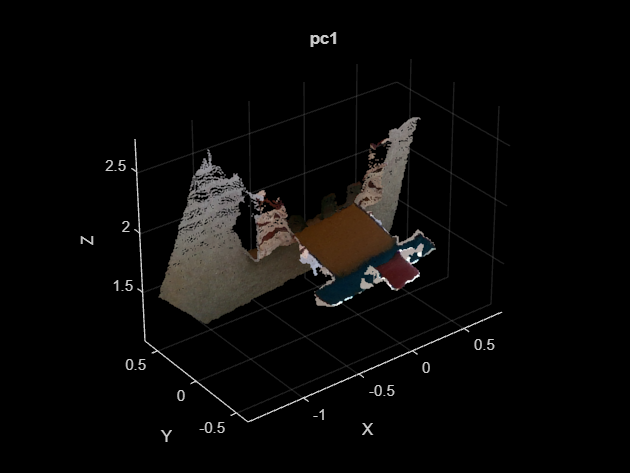

fig1=figure;
pcshow(pc1, "AxesVisibility","on")
xlabel('X');
ylabel('Y');
zlabel('Z');
title("pc1")

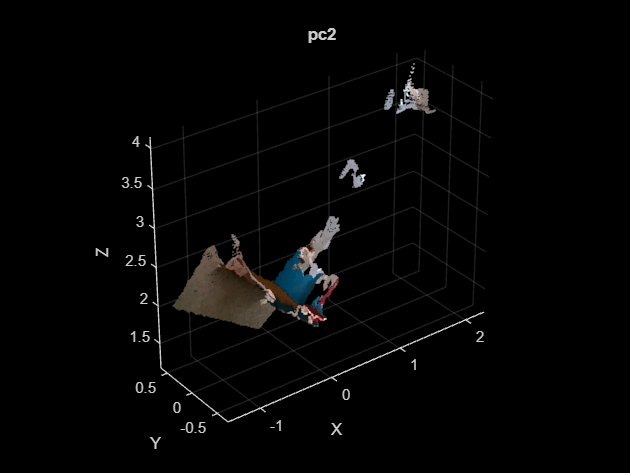

fig2=figure;
pcshow(pc2, "AxesVisibility","on")
xlabel('X');
ylabel('Y');
zlabel('Z');
title("pc2")